syms s

sys = s / ( (s + 2*pi) * (s + 10000) )

$$sys = \frac{s}{\left(s+6.2832\right)\,\left(s+10000\right)}$$

sys = collect(sys, s)

$$sys = \frac{s}{s^{2}+1.0006e+04\,s+6.2832e+04}$$


sys_tf = sym2tf(sys)

sys_tf =
 
            s
  ---------------------
  s^2 + 10006 s + 62832
 
Continuous-time transfer function.



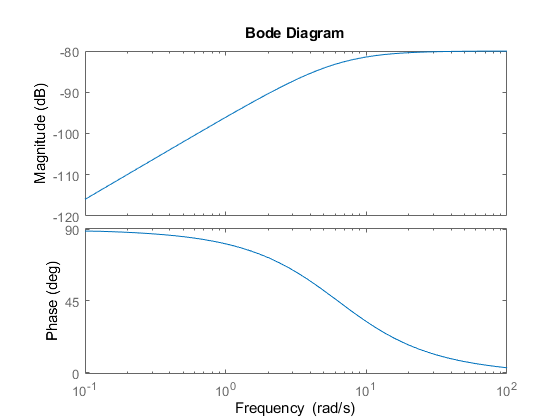


bode(sys_tf)

xlim([0.1 100])

clear ; close all ; clc

syms C_v C_m B R E P
% C_m = 0;

eq1 = E == R - (E*C_v1 + B*C_m1)*P_1

$$eq1 = \text{E}=R-P_{1}\,\left(B\,C_{\mathrm{m1}}+C_{\mathrm{v1}}\,\text{E}\right)$$

E = solve(eq1, E)

$$E = \frac{R-B\,C_{\mathrm{m1}}\,P_{1}}{C_{\mathrm{v1}}\,P_{1}+1}$$


eq2 = B == (E*C_v1 + B*C_m1) * P

$$eq2 = B=P_{1}\,\left(B\,C_{\mathrm{m1}}+\frac{C_{\mathrm{v1}}\,\left(R-B\,C_{\mathrm{m1}}\,P_{1}\right)}{C_{\mathrm{v1}}\,P_{1}+1}\right)$$


eq3 = solve(eq2, B)

$$eq3 = \frac{C_{\mathrm{v1}}\,P_{1}\,R}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+1}$$


sys = eq3 / R

$$sys = \frac{C_{\mathrm{v1}}\,P_{1}}{C_{\mathrm{v1}}\,P_{1}-C_{\mathrm{m1}}\,P_{1}+1}$$

clear ; close all ; clc
disp('-------------------------------------')

-------------------------------------


syms C_v1 C_m1 C_v2 C_m2 P_1 P_2 B H R E
% C_m = 0;
% C_m1 = 0;
% C_m2 = 0;
P_1 = 0;

eq1 = E == R - (E*C_v1 + B*C_m1)*P_1 - (E*C_v2 + B*C_m2)*P_2

$$eq1 = \text{E}=R-P_{2}\,\left(B\,C_{\mathrm{m2}}+C_{\mathrm{v2}}\,\text{E}\right)$$

E = solve(eq1, E)

$$E = \frac{R-B\,C_{\mathrm{m2}}\,P_{2}}{C_{\mathrm{v2}}\,P_{2}+1}$$


eq2 = B == (E*C_v1 + B*C_m1)* P_1;

$$eq2 = B=0$$

eq3 = H == (E*C_v2 + B*C_m1)* P_2;

$$eq3 = H=P_{2}\,\left(B\,C_{\mathrm{m1}}+\frac{C_{\mathrm{v2}}\,\left(R-B\,C_{\mathrm{m2}}\,P_{2}\right)}{C_{\mathrm{v2}}\,P_{2}+1}\right)$$


eq4 = solve(eq2, B);
eq5 = solve(eq3, H);

sys = eq5 / R;

sys = simplify(expand(sys))

$$sys = \frac{P_{2}\,\left(B\,C_{\mathrm{m1}}+C_{\mathrm{v2}}\,R+B\,C_{\mathrm{m1}}\,C_{\mathrm{v2}}\,P_{2}-B\,C_{\mathrm{m2}}\,C_{\mathrm{v2}}\,P_{2}\right)}{R\,\left(C_{\mathrm{v2}}\,P_{2}+1\right)}$$